# Averaging Filter

This example shows the recommended workflow for generating C code from a MATLAB function using the `codegen` command. These are the steps: 

1. Add the `%#codegen` directive to the MATLAB function to indicate that it is intended for code generation. This directive also enables the MATLAB code analyzer to identify warnings and errors specific to MATLAB for code generation.

2. Generate a MEX function to check that the MATLAB code is suitable for code generation. If errors occur, you should fix them before generating C code.

3. Test the MEX function in MATLAB to ensure that it is functionally equivalent to the original MATLAB code and that no run-time errors occur.

4. Generate C code.

5. Inspect the C code. 

## Prerequisites

There are no prerequisites for this example.

## About the `averaging_filter` Function

The `averaging_filter.m` function acts as an averaging filter on the input signal; it takes an input vector of values and computes an average for each value in the vector. The output vector is the same size and shape as the input vector.

type averaging_filter


% y = averaging_filter(x)
% Take an input vector signal 'x' and produce an output vector signal 'y' with
% same type and shape as 'x' but filtered.
function y = averaging_filter(x) %#codegen
% Use a persistent variable 'buffer' that represents a sliding window of
% 16 samples at a time.
persistent buffer;
if isempty(buffer)
    buffer = zeros(16,1);
end
y = zeros(size(x), class(x));
for i = 1:numel(x)
    % Scroll the buffer
    buffer(2:end) = buffer(1:end-1);
    % Add a new sample value to the buffer
    buffer(1) = x(i);
    % Compute the current average value of the window and
    % write result
    y(i) = sum(buffer)/numel(buffer);
end


The `%#codegen` compilation directive indicates that the MATLAB code is intended for code generation.

## Create Some Sample Data

Generate a noisy sine wave and plot the result.

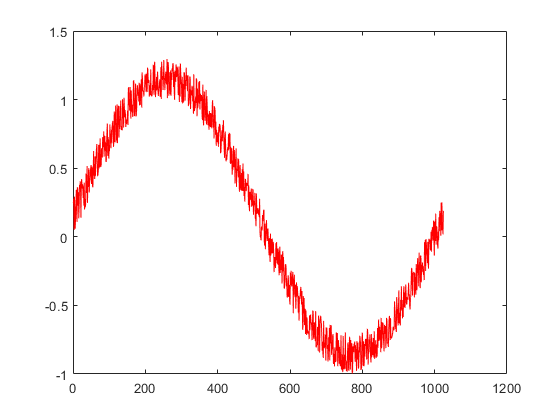

v = 0:0.00614:2*pi;
x = sin(v) + 0.3*rand(1,numel(v));
plot(x, 'red');

## Generate a MEX Function for Testing

Generate a MEX function using the `codegen` command. The `codegen` command checks that the MATLAB function is suitable for code generation and generates a MEX function that you can test in MATLAB prior to generating C code.

codegen averaging_filter -args {x}

Because C uses static typing, `codegen` must determine the properties of all variables in the MATLAB files at compile time. Here, the `-args` command-line option supplies an example input so that `codegen` can infer new types based on the input types. Using the sample signal created above as the example input ensures that the MEX function can use the same input.

By default, `codegen` generates a MEX function named `averaging_filter_mex` in the current folder. This allows you to test the MATLAB code and MEX function and compare the results.

## Test the MEX Function in MATLAB

Run the MEX function in MATLAB

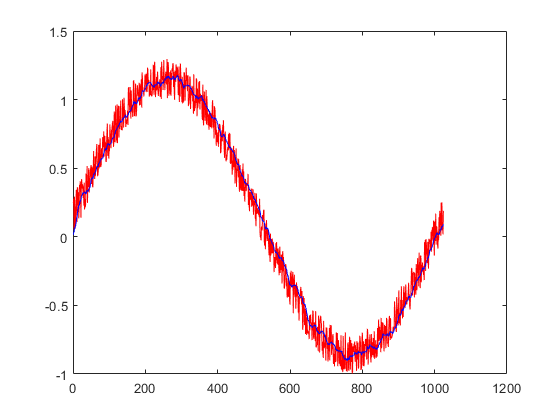

y = averaging_filter_mex(x);
% Plot the result when the MEX function is applied to the noisy sine wave.
% The 'hold on' command ensures that the plot uses the same figure window as
% the previous plot command.
hold on;
plot(y, 'blue');

## Generate C Code

codegen -config coder.config('lib') averaging_filter -args {x}

## Inspect the Generated Code

The `codegen` command with the `-config coder.config('lib')` option generates C code packaged as a standalone C library. The generated C code is in the `codegen/lib/averaging_filter/` folder. The files are:

dir codegen/lib/averaging_filter/


.                                averaging_filter_rtw.bat         codeInfo.mat                     
..                               averaging_filter_rtw.mk          codedescriptor.dmr               
averaging_filter.c               averaging_filter_rtw.rsp         examples                         
averaging_filter.h               averaging_filter_rtw_comp.rsp    interface                        
averaging_filter.lib             averaging_filter_rtw_ref.rsp     rtw_proj.tmw                     
averaging_filter.obj             averaging_filter_terminate.c     rtwtypes.h                       
averaging_filter_initialize.c    averaging_filter_terminate.h     setup_msvc150.bat                
averaging_filter_initialize.h    averaging_filter_terminate.obj   
averaging_filter_initialize.obj  averaging_filter_types.h         
averaging_filter_ref.rsp         buildInfo.mat                    



## Inspect the C Code for the `averaging_filter.c` Function

type codegen/lib/averaging_filter/averaging_filter.c


/*
 * Academic License - for use in teaching, academic research, and meeting
 * course requirements at degree granting institutions only.  Not for
 * government, commercial, or other organizational use.
 * File: averaging_filter.c
 *
 * MATLAB Coder version            : 4.1
 * C/C++ source code generated on  : 14-Mar-2019 20:57:53
 */

/* Include Files */
#include <string.h>
#include "averaging_filter.h"

/* Variable Definitions */
static double buffer[16];

/* Function Definitions */

/*
 * Use a persistent variable 'buffer' that represents a sliding window of
 *  16 samples at a time.
 * Arguments    : const double x[1024]
 *                double y[1024]
 * Return Type  : void
 */
void averaging_filter(const double x[1024], double y[1024])
{
  int i;
  double dv0[15];
  double b_y;
  int k;

  /*  y = averaging_filter(x) */
  /*  Take an input vector signal 'x' and produce an output vector signal 'y' with */
  /*  same type and shape as 'x' but filtered. */
  for (i = 0; i < 1024; 

*Copyright 2018 The MathWorks, Inc.*